## mat 2 tif


% v = vadmmtv;
% save_dir='./E0_recon_imgs_admmtv/'
% save_dir='./opto_recon_imgs_admmtv/'
% save_dir='./res_chart_recon_imgs_admmtv/'

v = vdenoise;
% save_dir='./E0_recon_imgs_gaptv+fastdvdnet/'
% save_dir='./opto_recon_imgs_gaptv+fastdvdnet/'
save_dir='./res_chart_recon_imgs_gaptv+fastdvdnet/'

save_dir = './res_chart_recon_imgs_gaptv+fastdvdnet/'


v(v>10.5)=0;
v(v>1)=1;
save_in1=0; save_type='.tif' ;save_rescale=1; save_class='uint16'

save_class = 'uint16'

save_img= v;


save_name='recon';

% run "iterative save image"

## show ROI


clear v_roi

v = vdenoise;

figure,imshow(v(:,:,3),[])

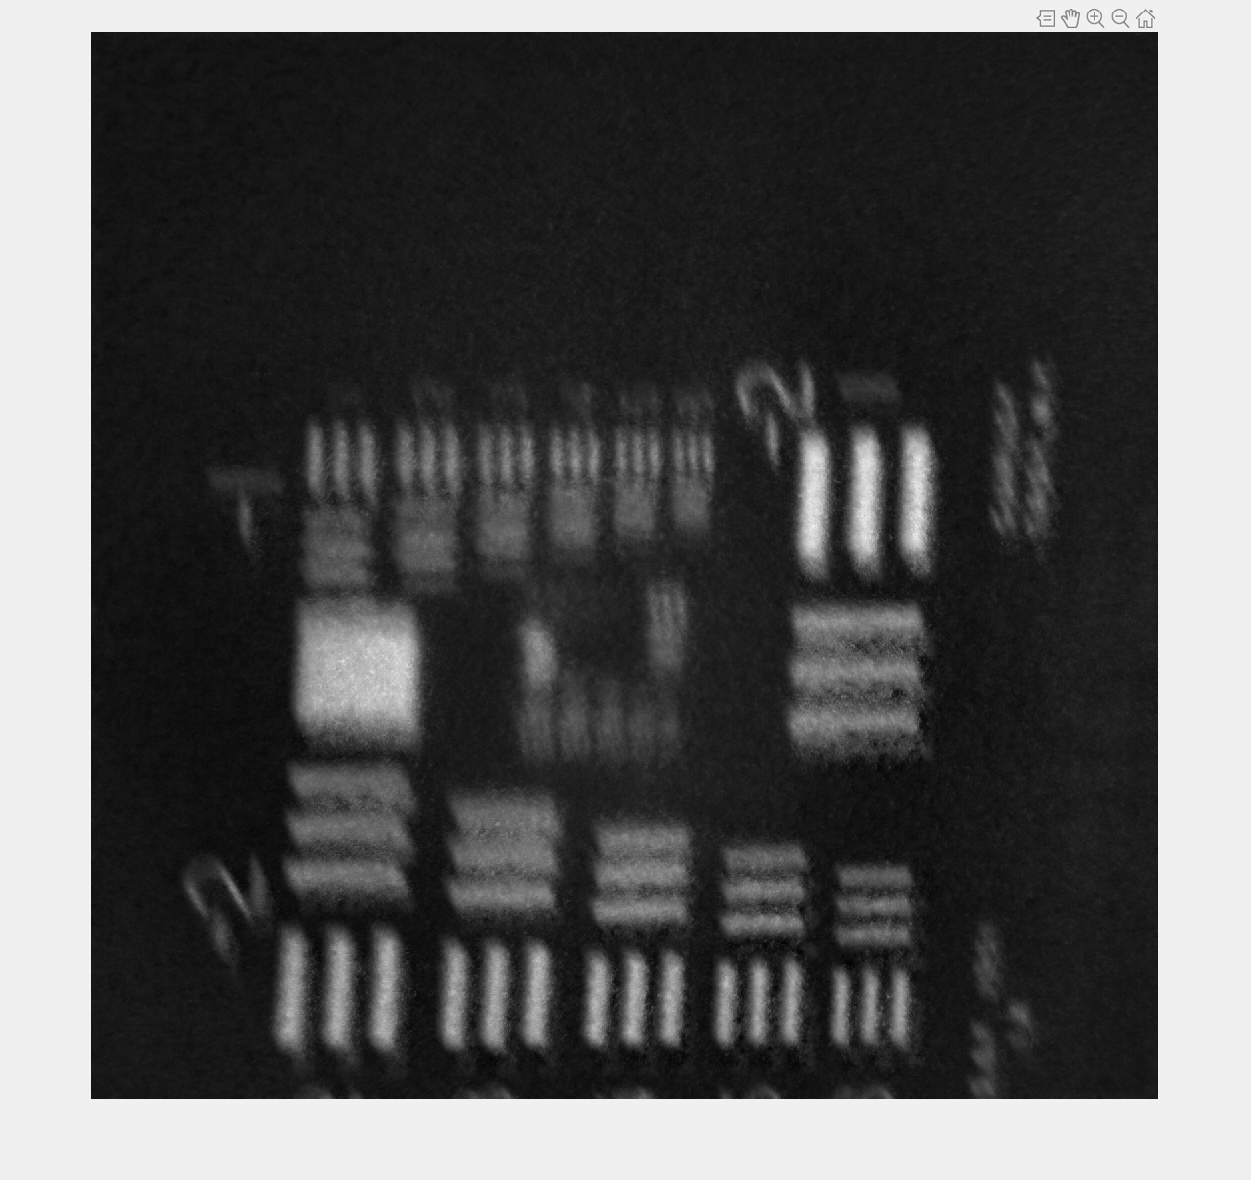

roi = getrect();

for k=1:size(v,3)
    v_roi(:,:,k) = imcrop(vdenoise(:,:,k),roi);
end
show_img =  v_roi;

save('v_roi.mat', 'v_roi')

## denoise

files = dir('./*.tif');
file_names = {files.name};
file_num = length(file_names);
imgs = zeros([3200 3200 file_num]);

for k=1:file_num
    imgs(:,:,k) = imread(file_names{k});
end

imgs(imgs>4)=0;
imgs(imgs>1)=1;

denoised_imgs   =  TV_denoising(imgs, 10,5);

% load("E:\project\CACTI\experiment\code\PnP_SCI_matlab\ffdnet_denoise-opt.mat")
% opt.sigma=0.08
% denoised_imgs = ffdnet_vdenoise(imgs,[],opt);

% show_img = denoised_imgs;

## save imgs

v = denoised_imgs ;
v(v>1.5)=0;
v(v>1)=1;
save_in1=0; save_type='.tif' ;save_rescale=1; save_class='uint16'

save_class = 'uint16'

save_img= v;
save_dir='./'

save_dir = './'

save_name='recon';